# Train Features

*Michael Caiola (Michael.Caiola@fda.hhs.gov) and Meijun Ye (Meijun.Ye@fda.hhs.gov)*

Live script used to train networks with feature data

Using PreDREEG, PreDREEGplot, and DREEGd, one can generate *_3F.mat files used in commented code below. Although these files are not included, the generated result is saved in AllFeatures.mat. The commented code is provided for reproducability.

% load("Sep22.mat")
% T = split(string(files(:,1)),'.');
% T = split(T(:,1),"\");
% T = T(:,end);
% F = table();
% %load("HEA_3F.mat")
% s = split(HEA_3F.names(:,1),"\");
% s = join([s(:,end-1),s(:,end)],"_");
% s = join([s HEA_3F.names(:,2)],"-");
% in = ismember(s,T);
% f = table(s(in),categorical(repmat("HEA",[sum(in),1])),HEA_3F.F(in,:),'VariableNames',["Filename","Label","Features"]);
% F = [F;f];
% %load("STR_3F.mat")
% s = split(STR_3F.names(:,1),"\");
% s = join([s(:,end-1),s(:,end)],"_");
% s = join([s STR_3F.names(:,2)],"-");
% in = ismember(s,T);
% f = table(s(in),categorical(repmat("STR",[sum(in),1])),STR_3F.F(in,:),'VariableNames',["Filename","Label","Features"]);
% F = [F;f];
% %load("TBI_3F.mat")
% s = split(TBI_3F.names(:,1),"\");
% s = join([s(:,end-1),s(:,end)],"_");
% s = join([s TBI_3F.names(:,2)],"-");
% in = ismember(s,T);
% f = table(s(in),categorical(repmat("TBI",[sum(in),1])),TBI_3F.F(in,:),'VariableNames',["Filename","Label","Features"]);
% F = [F;f];

Used Matched Age and Gender subjects/sessions of HEA and STR

# HEA subjects/sessions: 599/629
# STR subjects/sessions: 529/586
# TBI subjects/sessions: 552/629


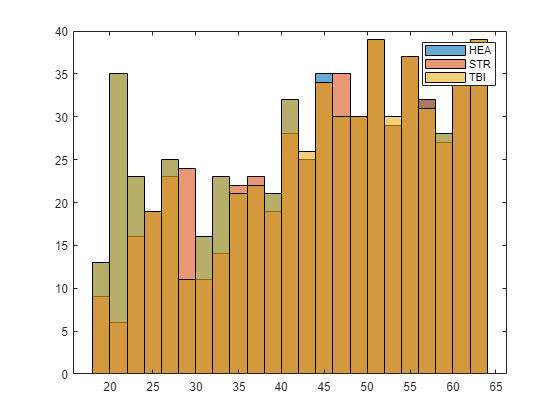

% [HEA,STR,TBI] = MatchSubjects();
% s = split(HEA.Location,'\');
% s = string(s(:,9));
% s = split(s,'.');
% HEA = s(:,1);
% s = split(STR.Location,'\');
% s = string(s(:,9));

% s = split(s,'.');
% STR = s(:,1);
% s = split(TBI.Location,'\');
% s = string(s(:,9));
% s = split(s,'.');
% TBI = s(:,1);
% HEA_in = [];
% for i  = 1:length(HEA)
%     HEA_in = [HEA_in; find(contains(F.Filename,HEA(i)))];
% end
% STR_in = [];
% for i  = 1:length(STR)
%     STR_in = [STR_in; find(contains(F.Filename,STR(i)))];
% end
% TBI_in = [];
% for i  = 1:length(TBI)
%     TBI_in = [TBI_in; find(contains(F.Filename,TBI(i)))];
% end
% in = [HEA_in; STR_in; TBI_in];
% F = F(in,:);
% featNames = getFeatureNames();
% f = array2table(F.Features);
% f.Properties.VariableNames = featNames;     

## LDA Feature Selection

Only need to generate once, can used saved data after.

% AMdl = fitcdiscr(F.Features,F.Label,'DiscrimType','linear',...
%             'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
%             struct('ShowPlots',false,'Verbose',1,'UseParallel',true,'Repartition',true,'SaveIntermediateResults',true));
% r = AMdl.DeltaPredictor;
% r_logical = r > mean(r)+std(r);
% gf = F.Features(:,r_logical);
% G = F;
% G.Features = gf;

First Minute Selection

% O = F(or(endsWith(F.Filename,"-1"),endsWith(F.Filename,"-2")),:);
% countcats(O.Label)
% OMdl = fitcdiscr(O.Features,O.Label,'DiscrimType','linear',...
%             'OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
%             struct('ShowPlots',false,'Verbose',1,'UseParallel',true,'Repartition',true));
% o = OMdl.DeltaPredictor;
% o_logical = o > mean(o)+std(o);
% h = O.Features(:,o_logical);
% H = O;
% H.Features = h;
% save("AllFeatures.mat","F","f","G","r_logical","r","O","o","o_logical","H");

## Load Feaures with LDA

load("AllFeatures.mat");

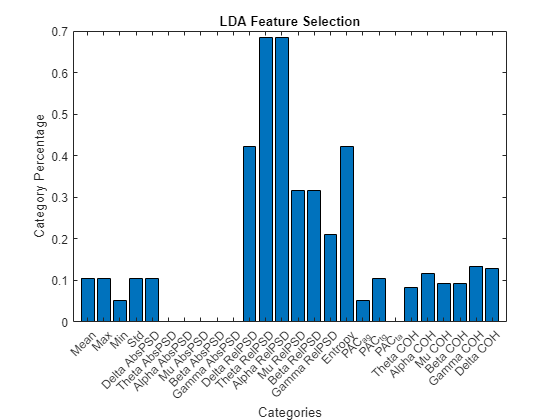

[varnames,varcats,ind] = MakeFeatureTableNames();
f = F.Features';
g = G.Features';
in = ismember(f,g,'rows');
LDAfeatures = varnames(in);
c = zeros(1,length(varcats));
for i = 1:length(c)
    c(i) = sum(contains(LDAfeatures,varcats(i)));
end
c = c./[repmat(19,[1,length(c)-6]), repmat(length(ind),[1,6])];
varcats(18) = "PAC_{ag}";
varcats(19) = "PAC_{tg}";
varcats(20) = "PAC_{ta}";
varcats = reordercats(categorical(varcats),varcats);
figure;
bar(varcats,c);
title("LDA Feature Selection")
ylabel("Percentage")
ylabel("Category Percentage")
xlabel("Categories")

%set(gca,'TickLabelInterpreter','none')

## Calculate ReliefF to rank top 100

Only need to run once

% [featureIndex,score] = relieff(...
%     F.Features, ...
%     F.Label, ...
%     10);
% save("RelieffScores.mat","featureIndex","score");

## Load Relief F scores

load("RelieffScores.mat")

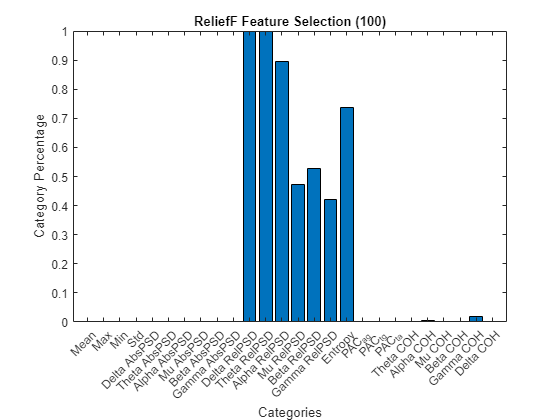

RFnames = varnames(featureIndex(1:100));    
c = zeros(1,length(varcats));
for i = 1:length(c)
    c(i) = sum(contains(RFnames,string(varcats(i))));
end
c = c./[repmat(19,[1,length(c)-6]), repmat(length(ind),[1,6])];
varcats(18) = "PAC_{ag}";
varcats(19) = "PAC_{tg}";
varcats(20) = "PAC_{ta}";
varcats = reordercats(categorical(varcats),string(varcats));
figure;
bar(varcats,c);
title("ReliefF Feature Selection (100)")%+ num2str(find(score(featureIndex)<.01,1)-1) +")")
ylabel("Category Percentage")
xlabel("Categories")

%set(gca,'TickLabelInterpreter','none')

## All Data

Using the Classification Learner, several SVM models were developed:

### ReliefF - Cubic SVM

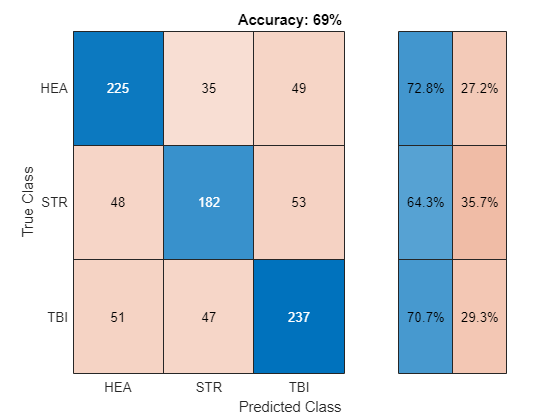

load('ReliefF_SVM.mat')
s = split(string(trainedModel1.ClassificationSVM.PredictorNames),'_');
s = s(:,:,2);
q = array2table(F.Features);
q = q(:,str2double(s));
q.Properties.VariableNames = trainedModel1.ClassificationSVM.X.Properties.VariableNames;
in = ismember(q,trainedModel1.ClassificationSVM.X,"rows");
testData = F(~in,:);
testLabels = F.Label(~in);

SVM = MdlResults(trainedModel1,testData,testLabels);
classify(SVM);

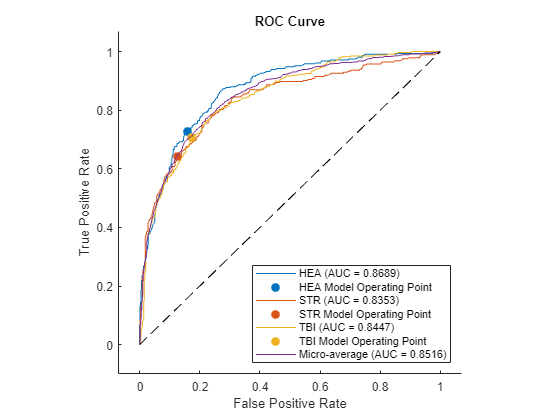

metrics(SVM);

### LDA - Medium Gaussian SVM

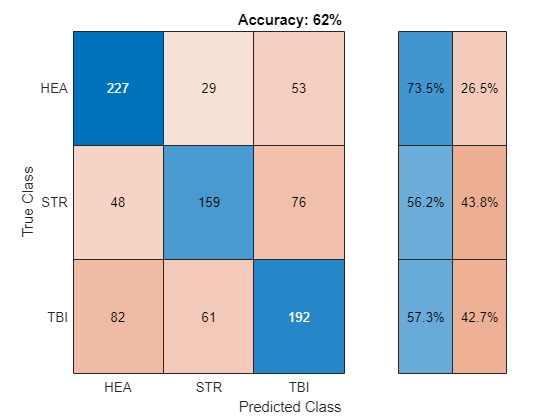

load('LDA_SVM.mat')
s = split(string(trainedModel.ClassificationSVM.PredictorNames),'_');
s = s(:,:,2);
q = array2table(G.Features);
q = q(:,str2double(s));
q.Properties.VariableNames = trainedModel.ClassificationSVM.X.Properties.VariableNames;
in = ismember(q,trainedModel.ClassificationSVM.X,"rows");
testData = G(~in,:);
testLabels = G.Label(~in);

SVM = MdlResults(trainedModel,testData,testLabels);
classify(SVM);

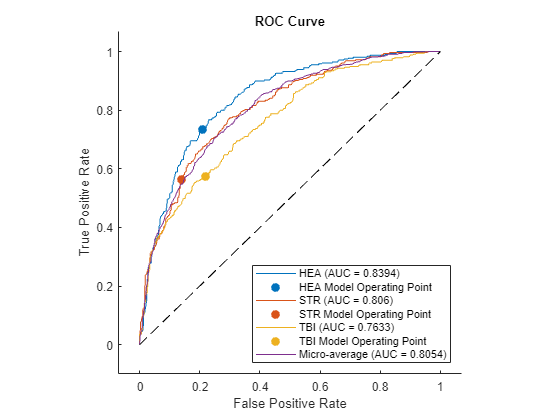

metrics(SVM);

### Deep Learning

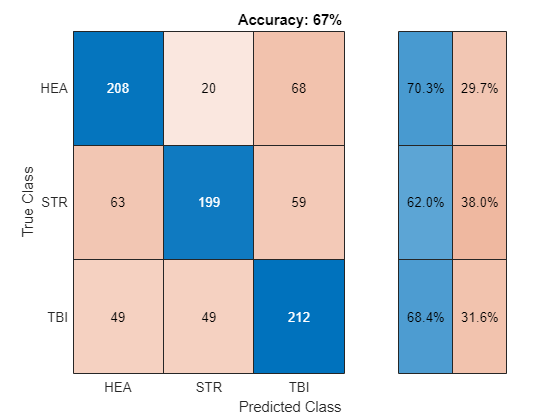

load("F_DL.mat","f_test","f_testL");
load("F_DL.mat","net5b")
load("RelieffScores.mat")
Fnet5b = MdlResults(net5b,f_test(:,featureIndex(1:100)),f_testL);
classify(Fnet5b);
metrics(Fnet5b);

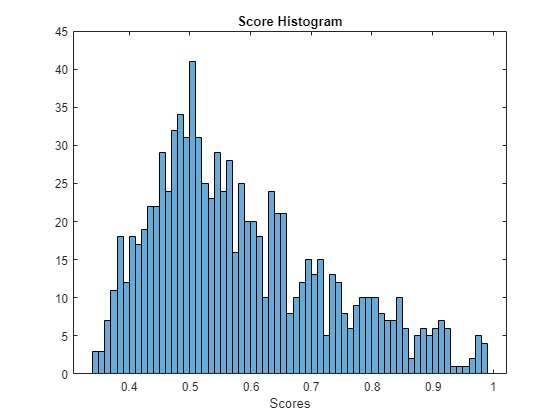

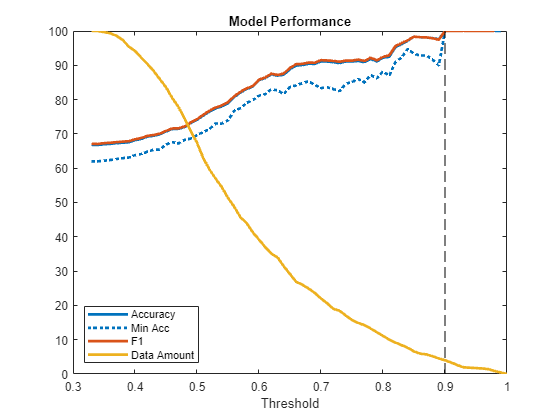

Data Remaining: 0.039914


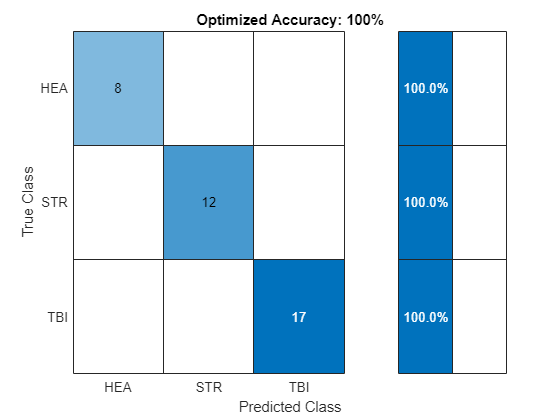

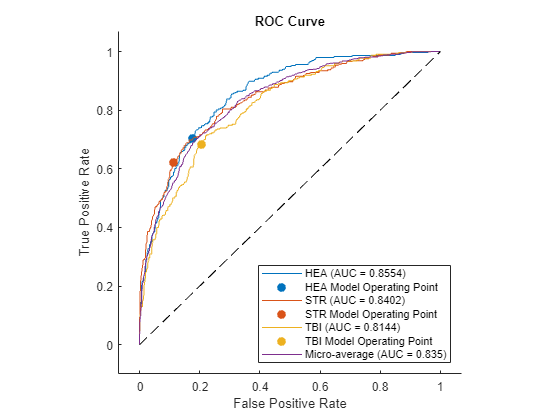

BinaryPlot(Fnet5b)

## **Disclaimer**

This software and documentation (the "Software") were developed at the Food and Drug Administration (FDA) by employees of the Federal Government in the course of their official duties. Pursuant to Title 17, Section 105 of the United States Code, this work is not subject to copyright protection and is in the public domain. Permission is hereby granted, free of charge, to any person obtaining a copy of the Software, to deal in the Software without restriction, including without limitation the rights to use, copy, modify, merge, publish, distribute, sublicense, or sell copies of the Software or derivatives, and to permit persons to whom the Software is furnished to do so. FDA assumes no responsibility whatsoever for use by other parties of the Software, its source code, documentation or compiled executables, and makes no guarantees, expressed or implied, about its quality, reliability, or any other characteristic. Further, use of this code in no way implies endorsement by the FDA or confers any advantage in regulatory decisions. Although this software can be redistributed and/or modified freely, we ask that any derivative works bear some notice that they are derived from it, and any modified versions bear some notice that they have been modified.The Software is not intended to make clinical diagnoses or to be used in any way to diagnose or treat subjects for whom the EEG is taken.

## Supporting Functions

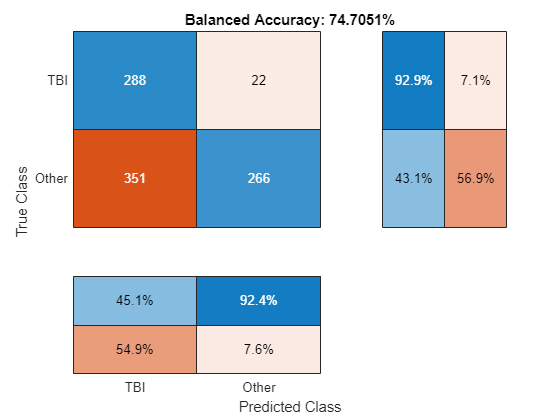

ans = single
0.7471

function names = getFeatureNames()

names = [];
chAppend = string();
for i = 1:19
    chAppend(i) = "_Ch" + i;
end
cats = ["Mean","Max","Min","Std","AbsPSD_Delta","AbsPSD_Theta","AbsPSD_Alpha",...
    "AbsPSD_Mu","AbsPSD_Beta","AbsPSD_Gamma","RelPSD_Delta","RelPSD_Theta",...
    "RelPSD_Alpha","RelPSD_Mu","RelPSD_Beta","RelPSD_Gamma","Entropy",...
    "PACag","PACtg","PACta",];
for i = 1:length(cats)
    for j = 1:19
        names = [names cats(i) + chAppend(j)];
    end
end
ind = [ 0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,...
        0,  0,  0,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,...
        1,  1,  1,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,...
        2,  2,  2,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,...
        3,  3,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,...
        5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  6,  6,  6,...
        6,  6,  6,  6,  6,  6,  6,  6,  6,  7,  7,  7,  7,  7,  7,  7,...
        7,  7,  7,  7,  8,  8,  8,  8,  8,  8,  8,  8,  8,  8,  9,  9,...
        9,  9,  9,  9,  9,  9,  9, 10, 10, 10, 10, 10, 10, 10, 10, 11,...
       11, 11, 11, 11, 11, 11, 12, 12, 12, 12, 12, 12, 13, 13, 13, 13,...
       13, 14, 14, 14, 14, 15, 15, 15, 16, 16, 17; 1,  2,  3,  4,  5,...
        6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16,...
       17, 18,  2,  3,  4,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15,...
       16, 17, 18,  3,  4,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15,...
       16, 17, 18,  4,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16,...
       17, 18,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16, 17, 18,...
        6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16, 17, 18,  7,  8,  9,...
       10, 11, 12, 13, 14, 15, 16, 17, 18,  8,  9, 10, 11, 12, 13, 14,...
       15, 16, 17, 18,  9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 10, 11,...
       12, 13, 14, 15, 16, 17, 18, 11, 12, 13, 14, 15, 16, 17, 18, 12,...
       13, 14, 15, 16, 17, 18, 13, 14, 15, 16, 17, 18, 14, 15, 16, 17,...
       18, 15, 16, 17, 18, 16, 17, 18, 17, 18, 18]+1;
bands = ["Theta","Alpha","Mu","Beta","Gamma","Delta"];
for i = 1:6
    for c = 1:length(ind)
        names = [names num2str(bands(i)) + "_Coherence_Ch" + ind(1,c) + "-Ch" + ind(2,c)'];
    end
end
end

function [varnames,varcats,ind] = MakeFeatureTableNames()
ind = [ 0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,  0,...
        0,  0,  0,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,  1,...
        1,  1,  1,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,  2,...
        2,  2,  2,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,  3,...
        3,  3,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,  4,...
        5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  5,  6,  6,  6,...
        6,  6,  6,  6,  6,  6,  6,  6,  6,  7,  7,  7,  7,  7,  7,  7,...
        7,  7,  7,  7,  8,  8,  8,  8,  8,  8,  8,  8,  8,  8,  9,  9,...
        9,  9,  9,  9,  9,  9,  9, 10, 10, 10, 10, 10, 10, 10, 10, 11,...
       11, 11, 11, 11, 11, 11, 12, 12, 12, 12, 12, 12, 13, 13, 13, 13,...
       13, 14, 14, 14, 14, 15, 15, 15, 16, 16, 17; 1,  2,  3,  4,  5,...
        6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16,...
       17, 18,  2,  3,  4,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15,...
       16, 17, 18,  3,  4,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15,...
       16, 17, 18,  4,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16,...
       17, 18,  5,  6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16, 17, 18,...
        6,  7,  8,  9, 10, 11, 12, 13, 14, 15, 16, 17, 18,  7,  8,  9,...
       10, 11, 12, 13, 14, 15, 16, 17, 18,  8,  9, 10, 11, 12, 13, 14,...
       15, 16, 17, 18,  9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 10, 11,...
       12, 13, 14, 15, 16, 17, 18, 11, 12, 13, 14, 15, 16, 17, 18, 12,...
       13, 14, 15, 16, 17, 18, 13, 14, 15, 16, 17, 18, 14, 15, 16, 17,...
       18, 15, 16, 17, 18, 16, 17, 18, 17, 18, 18]+1;

varnames = [];
varcats = [];
for i = 1:19
    varnames = [varnames, "Mean Ch"+i];
end
varcats = [varcats, "Mean"];
for i = 1:19
    varnames = [varnames, "Max Ch"+i];
end
varcats = [varcats, "Max"];
for i = 1:19
    varnames = [varnames, "Min Ch"+i];
end
varcats = [varcats, "Min"];
for i = 1:19
    varnames = [varnames, "Std Ch"+i];
end
varcats = [varcats, "Std"];
for i = 1:19
    varnames = [varnames, "Delta AbsPSD Ch"+i];
end
varcats = [varcats, "Delta AbsPSD"];
for i = 1:19
    varnames = [varnames, "Theta AbsPSD Ch"+i];
end
varcats = [varcats, "Theta AbsPSD"];
for i = 1:19
    varnames = [varnames, "Alpha AbsPSD Ch"+i];
end
varcats = [varcats, "Alpha AbsPSD"];
for i = 1:19
    varnames = [varnames, "Mu AbsPSD Ch"+i];
end
varcats = [varcats, "Mu AbsPSD"];
for i = 1:19
    varnames = [varnames, "Beta AbsPSD Ch"+i];
end
varcats = [varcats, "Beta AbsPSD"];
for i = 1:19
    varnames = [varnames, "Gamma AbsPSD Ch"+i];
end
varcats = [varcats, "Gamma AbsPSD"];
for i = 1:19
    varnames = [varnames, "Delta RelPSD Ch"+i];
end
varcats = [varcats, "Delta RelPSD"];
for i = 1:19
    varnames = [varnames, "Theta RelPSD Ch"+i];
end
varcats = [varcats, "Theta RelPSD"];
for i = 1:19
    varnames = [varnames, "Alpha RelPSD Ch"+i];
end
varcats = [varcats, "Alpha RelPSD"];
for i = 1:19
    varnames = [varnames, "Mu RelPSD Ch"+i];
end
varcats = [varcats, "Mu RelPSD"];
for i = 1:19
    varnames = [varnames, "Beta RelPSD Ch"+i];
end
varcats = [varcats, "Beta RelPSD"];
for i = 1:19
    varnames = [varnames, "Gamma RelPSD Ch"+i];
end
varcats = [varcats, "Gamma RelPSD"];
for i = 1:19
    varnames = [varnames, "Entropy Ch"+i];
end
varcats = [varcats, "Entropy"];
for i = 1:19
    varnames = [varnames, "PAC_ag Ch"+i];
end
varcats = [varcats, "PAC_ag"];
for i = 1:19
    varnames = [varnames, "PAC_tg Ch"+i];
end
varcats = [varcats, "PAC_tg"];
for i = 1:19
    varnames = [varnames, "PAC_ta Ch"+i];
end
varcats = [varcats, "PAC_ta"];
for i = 1:length(ind)
    varnames = [varnames, "Theta COH ch"+ind(1,i)+"-ch"+ind(2,i)];
end
varcats = [varcats, "Theta COH"];
for i = 1:length(ind)
    varnames = [varnames, "Alpha COH ch"+ind(1,i)+"-ch"+ind(2,i)];
end
varcats = [varcats, "Alpha COH"];
for i = 1:length(ind)
    varnames = [varnames, "Mu COH ch"+ind(1,i)+"-ch"+ind(2,i)];
end
varcats = [varcats, "Mu COH"];
for i = 1:length(ind)
    varnames = [varnames, "Beta COH ch"+ind(1,i)+"-ch"+ind(2,i)];
end
varcats = [varcats, "Beta COH"];
for i = 1:length(ind)
    varnames = [varnames, "Gamma COH ch"+ind(1,i)+"-ch"+ind(2,i)];
end
varcats = [varcats, "Gamma COH"];
for i = 1:length(ind)
    varnames = [varnames, "Delta COH ch"+ind(1,i)+"-ch"+ind(2,i)];
end
varcats = [varcats, "Delta COH"];
end